%通过暴力迭代的方法来搜索使R最大的p的值
clear;

syms p C1 C2 B0
%当p<=pt时u的最大值
u_bmax=(2*p*log(-(2*p - C1*C2 + C1*C2*sqrt(-(4*p - C1*C2)/(C1*C2)))/(2*p)) + C1*C2 - 2*B0*C2*p + C1*C2*sqrt(-(4*p - C1*C2)/(C1*C2)))/(2*C2);
b_max=B0 - log(-(2*p - C1*C2 + C1*C2*sqrt(-(4*p - C1*C2)/(C1*C2)))/(2*p))/C2;  %在p<=pt时时有意义
%pt的表达式
pt=C1*C2/4;
%当p>pt时，只会取B0点，此时只会的效用为
ut=C1/2-p*B0;

C1_vec = [80,40,100,70,50,70,60,110]; %C1_vec(i)为第i个用户的C1参数,C2_vec,B0_vec同理
C2_vec = [0.5,0.5,0.6,0.2,0.4,0.1,0.4,0.7];
B0_vec = [40,50,80,40,40,40,60,55];
C1_len = length(C1_vec);
C2_len = length(C2_vec);
B0_len = length(B0_vec);
if C1_len~=C2_len  || C1_len~=B0_len
    fprintf("输入参数的数量不一致")
end

pt_vec = [];  %pt_vec(i)表示用户i的pt值
ut_vec =cell(1); %ut_vec(i)表示用户i在p>pt时在满意点B0的效用计算公式（当p>pt，满意点收缩到只剩B0一个点）
y_vec=cell(1);  %y_vec(i)表示用户i在 p<=pt 时在满意区间[B0,+inf]最大值的计算公式
bmax_vec=cell(1); %bmax_vec(i)表示用户i 在p<pt时的最大值所对应的带宽值bmax
%生成各个向量
for i=1:C1_len
    tem_pt=subs(pt,[C1,C2],[C1_vec(i),C2_vec(i)]);
    pt_vec=[pt_vec,tem_pt];
    tem_ut=subs(ut,[C1,B0],[C1_vec(i),B0_vec(i)]);
    ut_vec{i}=matlabFunction(tem_ut);
    tem_y = subs(u_bmax,[C1,C2,B0],[C1_vec(i),C2_vec(i),B0_vec(i)]);
    y_vec{i}=matlabFunction(tem_y);
    tem_bmax=subs(b_max,[C1,C2,B0],[C1_vec(i),C2_vec(i),B0_vec(i)]);
    bmax_vec{i} = matlabFunction(tem_bmax);
end

price = 0:0.01:10;
R = [];
utility= [];
for i=price
    R = [R,-Revenue_max_func(i,pt_vec,ut_vec,y_vec,B0_vec,bmax_vec)];
    utility=[utility,-Utility_max_func(i,pt_vec,ut_vec,y_vec,B0_vec,bmax_vec)];
end
maxMixUtility=[];
maxMixUtilityPrice = [];
%遍历alpha下的混合效用
alpha=0:0.01:1

alpha =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


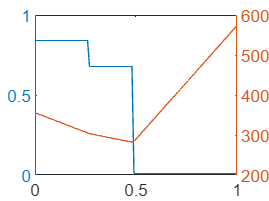

for i=alpha
RevenueMixUtility = (1-i).*R + i.*utility;
[MixUtility,index]=max(RevenueMixUtility);
maxMixUtility = [maxMixUtility,MixUtility];
maxMixUtilityPrice = [maxMixUtilityPrice,price(index)];
end
figure
yyaxis left
plot(alpha,maxMixUtilityPrice)
yyaxis right
plot(alpha,maxMixUtility)

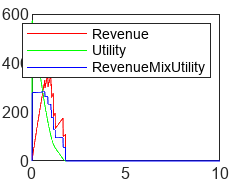

figure
% 确定alpha下画出混合效用
alpha = 0.48;
RevenueMixUtility = (1-alpha).*R + alpha.*utility;
figure();
plot(price,R,'r')
hold on
plot(price,utility,'g');
plot(price,RevenueMixUtility,'b');
legend('Revenue','Utility','RevenueMixUtility');